**Introduction**

This document is to explore the waveform of OTFS in ***integer Dopplers***. Here, we have 4 kinds of testings.

- Case 1: the h[0] starts at the actual beginning of the signal, i.e., 1st CP. $h[0, 1, 2, 3, 4, 5, 6]*s[-2,-1, 0, 1, 2, 3, 4]$

- Case 2: the h[0] starts at the original signal: $h[-2,-1, 0, 1, 2, 3, 4]*s[-2,-1, 0, 1, 2, 3, 4]$

- Case 3: the h[0] starts at the original signal, but the CP part uses the channel on data, i.e., $h[3, 4, 0, 1, 2]*s[3, 4, 0, 1, 2]$

- Case 4: the h[0] starts at the actual beginning of the signal without any CP.$[0, 0, h[0, 1, 2, 3, 4]*s[0, 1, 2, 3, 4]]$

**Basic settings**

clear;
clc;
N = 4;                          % time slot number
M = 4;                         % subcarrier number
x2_delay_pos = 4;
x = zeros(N, M);    
x(1,1) = 1+1j;
x(1,x2_delay_pos) = 1+1j;
hi = 1;
li = 2;
ki = 1;
cp_len = 4

cp_len = 4

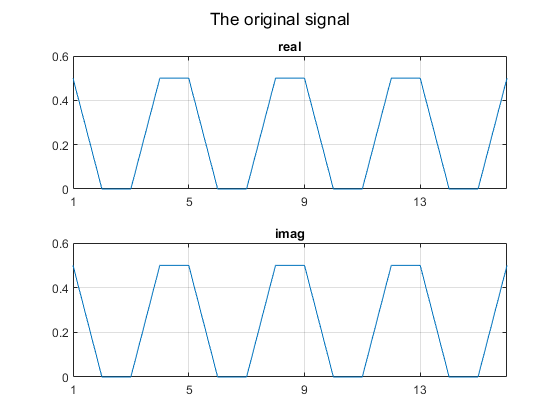

% modulation
s = OTFS_modulation(N,M,x);
plot_s(s, M, N);

% add cp
s_cp = [s(N*M-cp_len+1:N*M);s];

% estimate the outcome
yest1_viterbo = (N-1)/N*exp(2j*pi*(1-1)/M*ki/N)*exp(-2j*pi*mod(2-ki, N)/N)*(1+1j);
yest1_viterbo_noweight = exp(2j*pi*(1-1)/M*ki/N)*exp(-2j*pi*mod(2-ki, N)/N)*(1+1j);
yest1_viterbo_noweight2 = exp(2j*pi*(1-1)/M*ki/N)*exp(2j*pi*mod(2-ki, N)/N)*(1+1j);
yest1 = exp(2j*pi*(1-1)/M*ki/N)*(1+1j);
yest2_viterbo = (N-1)/N*exp(2j*pi*(x2_delay_pos-1)/M*ki/N)*exp(-2j*pi*mod(2-ki, N)/N)*(1+1j);
yest2_viterbo_noweight = exp(2j*pi*(x2_delay_pos-1)/M*ki/N)*exp(-2j*pi*mod(2-ki, N)/N)*(1+1j);
yest2 = exp(2j*pi*(x2_delay_pos-1)/M*ki/N)*(1+1j);
% recalculate the channel
yest2_xpos_M = x2_delay_pos + li;
if yest2_xpos_M > M
    yest2_xpos_M = yest2_xpos_M - M;
end

**Case 1: Our channel 1**

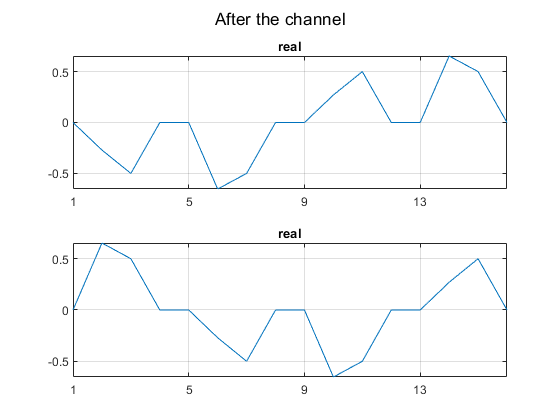

% pass the channel
case1_s_chan = hi*circshift([s_cp.*exp(1j*2*pi/M*(0:M*N+cp_len-1)*ki/N).';zeros(cp_len,1)],li);
case1_r = case1_s_chan(cp_len+1:cp_len+(N*M));
plot_r(case1_r, M, N);

% to Rx DD domain
case1_y = OTFS_demodulation(N,M,case1_r);
% compare
disp("Our channel 1: ")

Our channel 1: 


fprintf(" - The actual y at (%d, %d): %.4f %+.4fj\n", 1+ki, 1+li, real(case1_y(1+ki, 1+li)), imag(case1_y(1+ki, 1+li)));

 - The actual y at (2, 3): -1.0000 +1.0000j


yest1_viterbo

yest1_viterbo = 0.7500 - 0.7500i

yest1_viterbo_noweight

yest1_viterbo_noweight = 1.0000 - 1.0000i

yest1_viterbo_noweight2

yest1_viterbo_noweight2 = -1.0000 + 1.0000i

yest1

yest1 = 1.0000 + 1.0000i

fprintf(" - The actual y at (%d, %d): %.4f %+.4fj\n", 1+ki, yest2_xpos_M, real(case1_y(1+ki, yest2_xpos_M)), imag(case1_y(1+ki, yest2_xpos_M)));

 - The actual y at (2, 2): -0.5412 +1.3066j


yest2_viterbo

yest2_viterbo = 0.9799 + 0.4059i

yest2_viterbo_noweight

yest2_viterbo_noweight = 1.3066 + 0.5412i

yest2

yest2 = -0.5412 + 1.3066i

Here, we can see that the current Viterbo's method does not estimate the channel for $0<l<l_{\max }$. The problem happens in how to pass signal through the channel.

**Case 2: Emanuele Viterbo Channel in time domain**

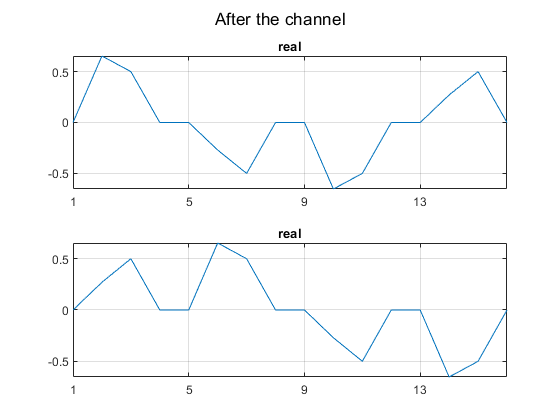

% pass the channel
case2_s_chan_0delay = hi*[s_cp.*exp(1j*2*pi/M*(-cp_len:M*N-1)*ki/N).';zeros(cp_len,1)];
case2_s_chan = hi*circshift([s_cp.*exp(1j*2*pi/M*(-cp_len:M*N-1)*ki/N).';zeros(cp_len,1)],li);
case2_r = case2_s_chan(cp_len+1:cp_len+(N*M));
plot_r(case2_r, M, N);

% to Rx DD domain
case2_y = OTFS_demodulation(N,M,case2_r);
% compare
disp("Emanuele Viterbo channel:")

Emanuele Viterbo channel:


fprintf(" - The actual y at (%d, %d): %.4f %+.4fj\n", 1+ki, 1+li, real(case2_y(1+ki, 1+li)), imag(case2_y(1+ki, 1+li)));

 - The actual y at (2, 3): 1.0000 +1.0000j


yest1_viterbo

yest1_viterbo = 0.7500 - 0.7500i

yest1_viterbo_noweight

yest1_viterbo_noweight = 1.0000 - 1.0000i

yest1

yest1 = 1.0000 + 1.0000i

fprintf(" - The actual y at (%d, %d): %.4f %+.4fj\n", 1+ki, yest2_xpos_M, real(case2_y(1+ki, yest2_xpos_M)), imag(case2_y(1+ki, yest2_xpos_M)));

 - The actual y at (2, 2): 1.3066 +0.5412j


yest2_viterbo

yest2_viterbo = 0.9799 + 0.4059i

yest2_viterbo_noweight

yest2_viterbo_noweight = 1.3066 + 0.5412i

yest2

yest2 = -0.5412 + 1.3066i

**Case 3: Our Alternative Channel in time domain**

% pass the channel
case3_s_chan = hi*circshift(s.*exp(1j*2*pi/M*(0:M*N-1)*ki/N).',li);
case3_r = case3_s_chan;
plot_r(case3_r, M, N);

% to Rx DD domain
case3_y = OTFS_demodulation(N,M,case3_r);
% compare
disp("Emanuele Viterbo channel:")

Emanuele Viterbo channel:


fprintf(" - The actual y at (%d, %d): %.4f %+.4fj\n", 1+ki, 1+li, real(case3_y(1+ki, 1+li)), imag(case3_y(1+ki, 1+li)));

 - The actual y at (2, 3): 1.0000 +1.0000j


if case3_y(1+ki, 1+li) - case2_y(1+ki, 1+li) < eps
    fprintf("   - This value is Emanuele Viterbo's channel.\n");
end

   - This value is Emanuele Viterbo's channel.


yest1_viterbo

yest1_viterbo = 0.7500 - 0.7500i

yest1_viterbo_noweight

yest1_viterbo_noweight = 1.0000 - 1.0000i

yest1

yest1 = 1.0000 + 1.0000i

fprintf(" - The actual y at (%d, %d): %.4f %+.4fj\n", 1+ki, yest2_xpos_M, real(case3_y(1+ki, yest2_xpos_M)), imag(case3_y(1+ki, yest2_xpos_M)));

 - The actual y at (2, 2): 1.3066 +0.5412j


if case3_y(1+ki, yest2_xpos_M) - case2_y(1+ki, yest2_xpos_M) < eps
    fprintf("   - This value is Emanuele Viterbo's channel.\n");
end

   - This value is Emanuele Viterbo's channel.


yest2_viterbo

yest2_viterbo = 0.9799 + 0.4059i

yest2_viterbo_noweight

yest2_viterbo_noweight = 1.3066 + 0.5412i

yest2

yest2 = -0.5412 + 1.3066i

**Case 4: No CP using our channel**

In this case, our channel model is the same as Emanuele's.

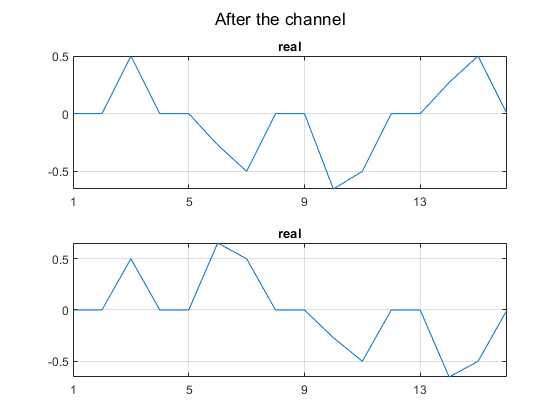

% pass the channel
case4_s_chan = hi*circshift([s.*exp(1j*2*pi/M*(0:M*N-1)*ki/N).';zeros(cp_len,1)],li);
case4_r = case4_s_chan(1:M*N);
plot_r(case4_r, M, N);

% to Rx DD domain
case4_y = OTFS_demodulation(N,M,case4_r);
% compare
disp("No CP using our channel 1:")

No CP using our channel 1:


fprintf(" - The actual y at (%d, %d): %.4f %+.4fj\n", 1+ki, 1+li, real(case4_y(1+ki, 1+li)), imag(case4_y(1+ki, 1+li)));

 - The actual y at (2, 3): 1.0000 +1.0000j


yest1_viterbo

yest1_viterbo = 0.7500 - 0.7500i

yest1_viterbo_noweight

yest1_viterbo_noweight = 1.0000 - 1.0000i

yest1_viterbo_noweight2

yest1_viterbo_noweight2 = -1.0000 + 1.0000i

yest1

yest1 = 1.0000 + 1.0000i

fprintf(" - The actual y at (%d, %d): %.4f %+.4fj\n", 1+ki, yest2_xpos_M, real(case4_y(1+ki, yest2_xpos_M)), imag(case4_y(1+ki, yest2_xpos_M)));

 - The actual y at (2, 2): 0.9799 +0.4059j


yest2_viterbo

yest2_viterbo = 0.9799 + 0.4059i

yest2_viterbo_noweight

yest2_viterbo_noweight = 1.3066 + 0.5412i

yest2

yest2 = -0.5412 + 1.3066i

**Functions**

function plot_s(s, M, N)
    figure("name", "The original signal")
    subplot(2,1,1)
    plot(real(s));
    title("real");
    xlim([1, N*M]);
    xticks(1:M:(N*M+1));
    grid on;
    subplot(2,1,2)
    plot(imag(s));
    title("imag");
    xlim([1, N*M]);
    xticks(1:M:(N*M+1));
    grid on;
    sgtitle("The original signal")
end
function plot_r(r, M, N)
    figure("name", "Time domain")
    subplot(2,1,1)
    plot(real(r));
    title("real");
    xlim([1, N*M]);
    xticks(1:M:(N*M+1));
    grid on;
    subplot(2,1,2)
    plot(imag(r));
    title("real");
    xlim([1, N*M]);
    xticks(1:M:(N*M+1));
    grid on;
    sgtitle("After the channel")
end